# A simple reembeding demo

## with a small dataset included in the repo to display the notation and basic operations

clear; gcp; % start a parallel engine

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 1).
Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 6).


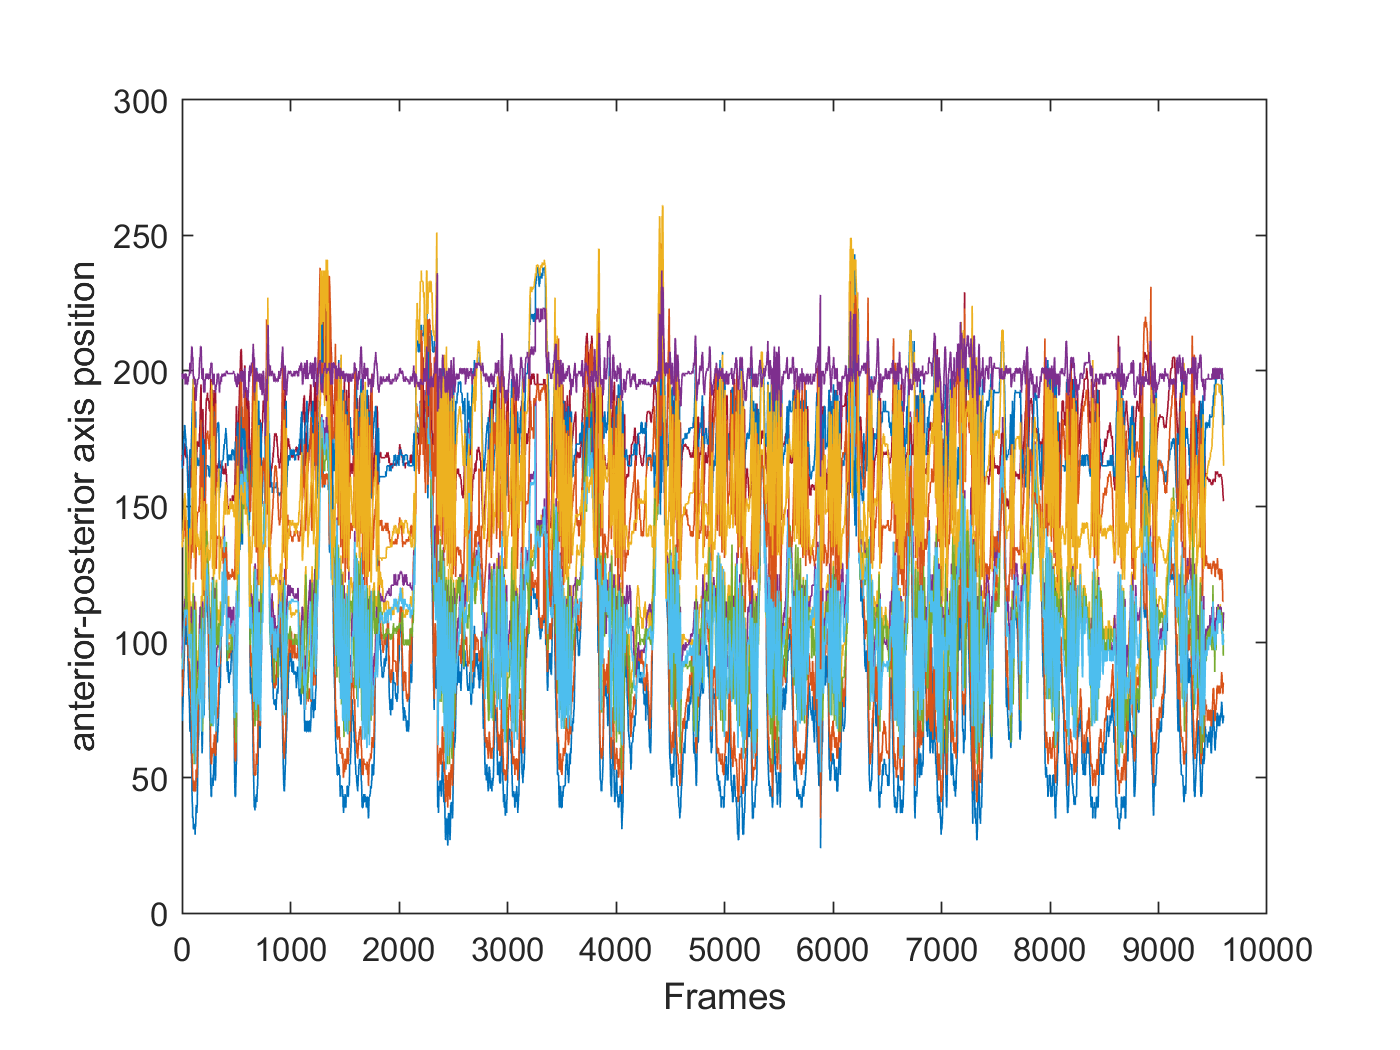


% Find base repository path (where this file is contained)
basePath = fileparts(which('demo_reimbedding'));
% Add to MATLAB path
idcs   = strfind(basePath,filesep);
addpath(genpath(fullfile(basePath(1:idcs(end)-1))));

% load LEAP output and plot body parts predictions for fragment of the movie
jj=h5read("demo_MMM_LEAPpred.h5", '/positions_pred');
juse = [1 2 5 6 7 8 12 13 14 15 16];%[1 8 7 12 13 16 17 18];
idxs = 40001:49600; % frames to visualize
figure;
for i=juse
    plot(squeeze(jj(i,2,idxs))); hold on
end
set(gca,'PlotBoxAspectRatio',[1 0.75 1]); ylabel('anterior-posterior axis position'); xlabel('Frames');

## calculate distances from body part positions

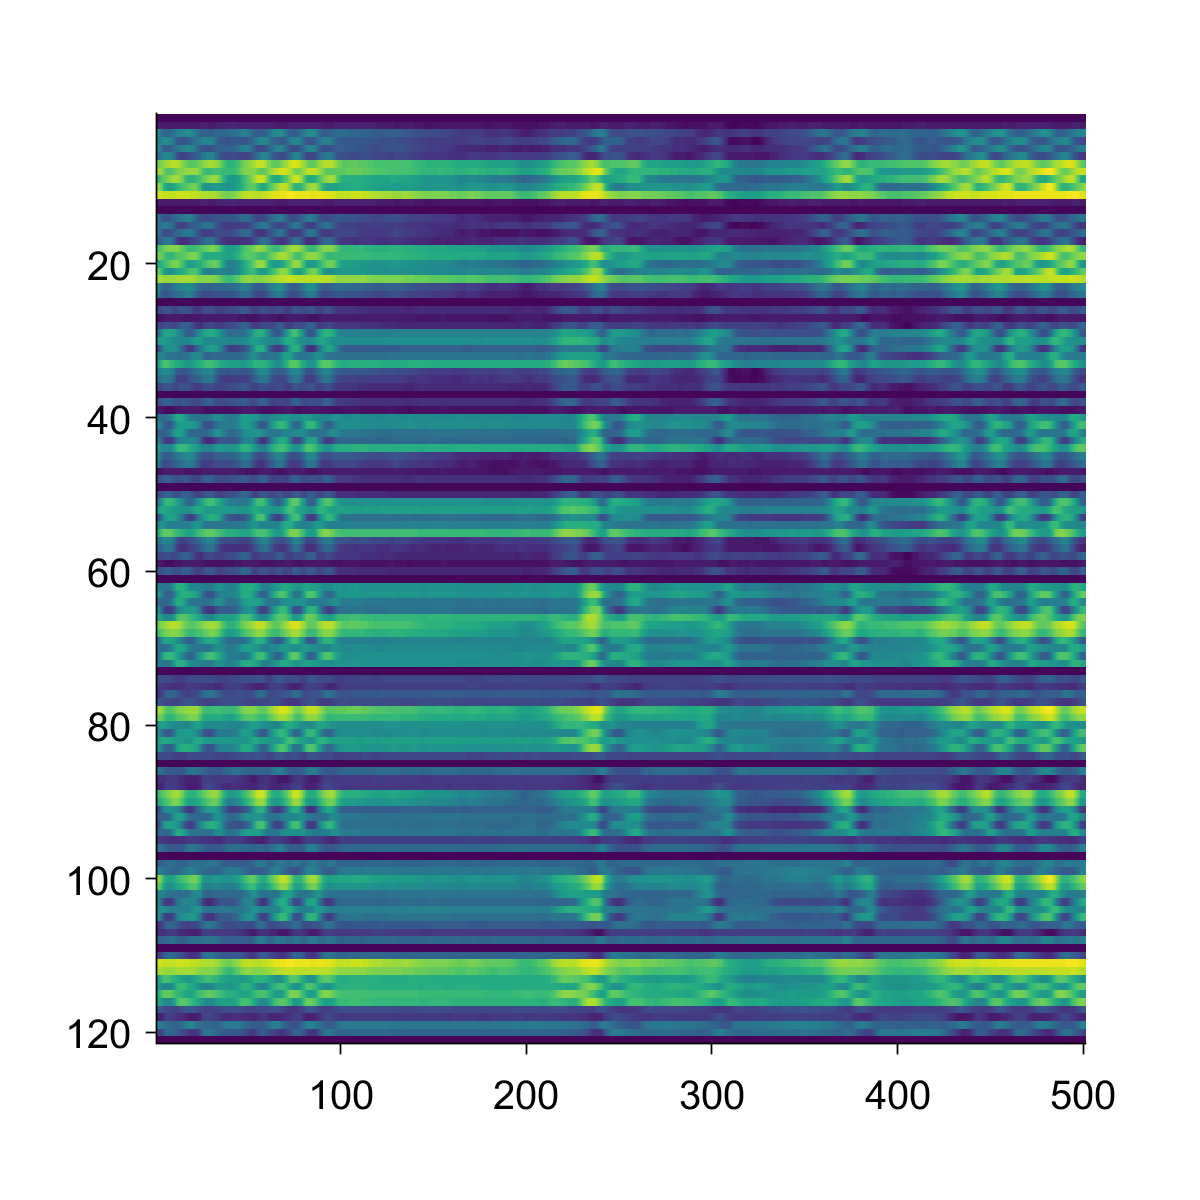

xIdx = juse;
yIdx = juse;
[X, Y] = meshgrid(xIdx,yIdx);
X = X(:); Y = Y(:);
IDX = find(X~=Y);

p1 = jj;
p1Dist = zeros(size(juse,2)*size(juse,2),size(p1,3));

for ii = 1:size(p1Dist,1)
    p1Dist(ii,:) = returnDist(squeeze(p1(X(ii),:,:)),squeeze(p1(Y(ii),:,:)));
end

p1Dsmooth = zeros(size(p1Dist));
for ii = 1:size(p1Dist,1)
    p1Dsmooth(ii,:) = medfilt1(smooth(p1Dist(ii,:),'moving',5,'omitnan'),5, 'omitnan');
end

p1Dist = p1Dsmooth;
figure;
imagesc(p1Dist(:,idxs(4500:5000)));
colormap viridis
prepfig; xlabel('Frames');

## make PCA projections of distances

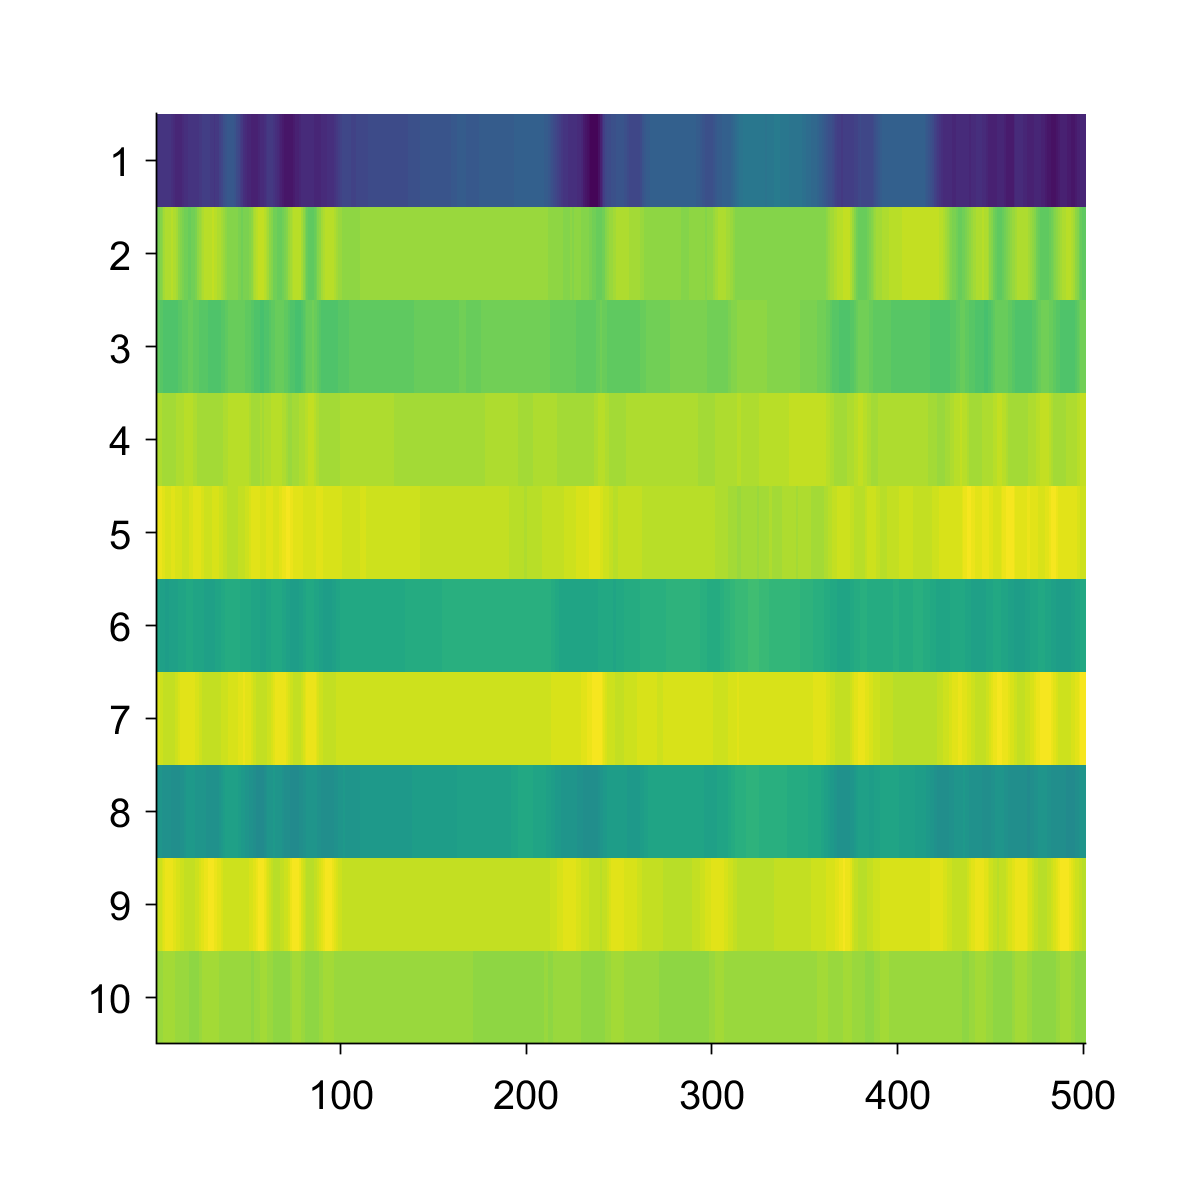

load('vecsVals_subSelect.mat')

numProjections = 10; numModes = 10; pcaModes = 10;
p2Dist = bsxfun(@minus,p1Dist(1:110,:),muv');
DistProjections = p2Dist'*vecs(:,1:numProjections);
figure;
imagesc(DistProjections(idxs(4500:5000),:)');
colormap viridis
prepfig; ylabel('PCA projection'); xlabel('Frames');

## Wavelet transform

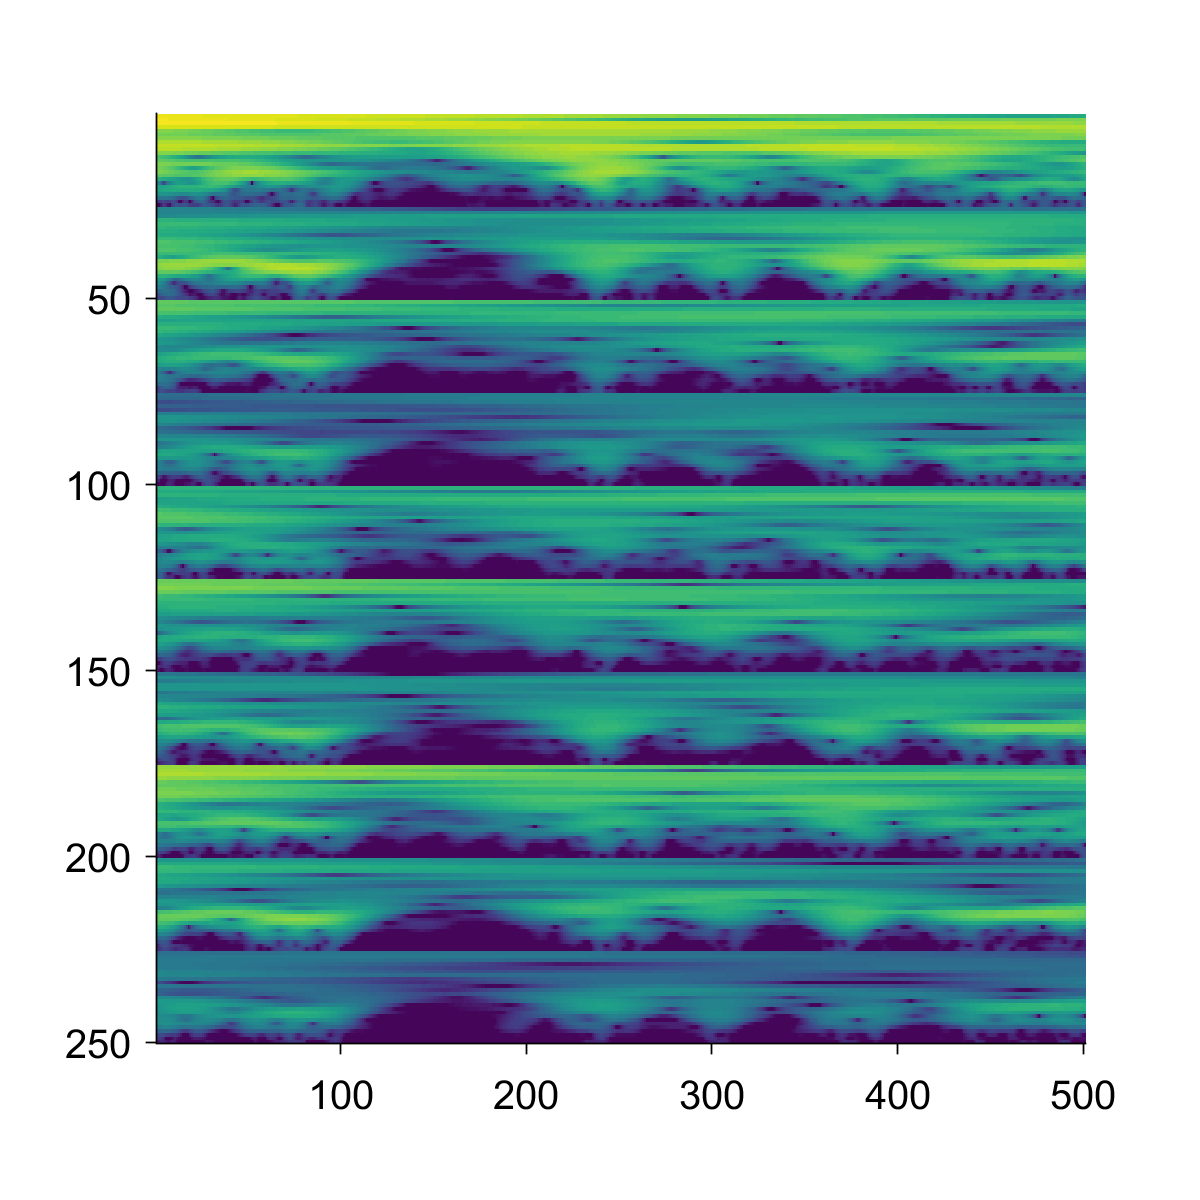

parameters = setRunParameters([]);
parameters.pcaModes = 10;
parameters.samplingFreq = 80;
parameters.minF = .25;
parameters.maxF = 20;
parameters.numModes = numModes;

[data,f] = findWavelets(DistProjections,numModes,parameters);
data = log(data); data(data<-3) = -3;
figure;
imagesc(data(idxs(4500:5000),:)');
colormap viridis
prepfig; ylabel([]); xlabel('Frames');

## Embedding new data to behavior space

% load training dataset
load('trainingSet_new10.mat')

trainingData = dataAll; trainingEmbedding = ydata; cdata1 = C100;

KK = 101;
[cGuesses,pClusts] = reembedHDK(DistProjections,parameters,trainingData,cdata1,KK);

	 Processing batch #   1 out of    5
Size of current Data = 20000    250
	 Processing batch #   2 out of    5
Size of current Data = 20000    250
	 Processing batch #   3 out of    5
Size of current Data = 20000    250
	 Processing batch #   4 out of    5
Size of current Data = 20000    250
	 Processing batch #   5 out of    5
Size of current Data = 15998    250


## Behavior clusters

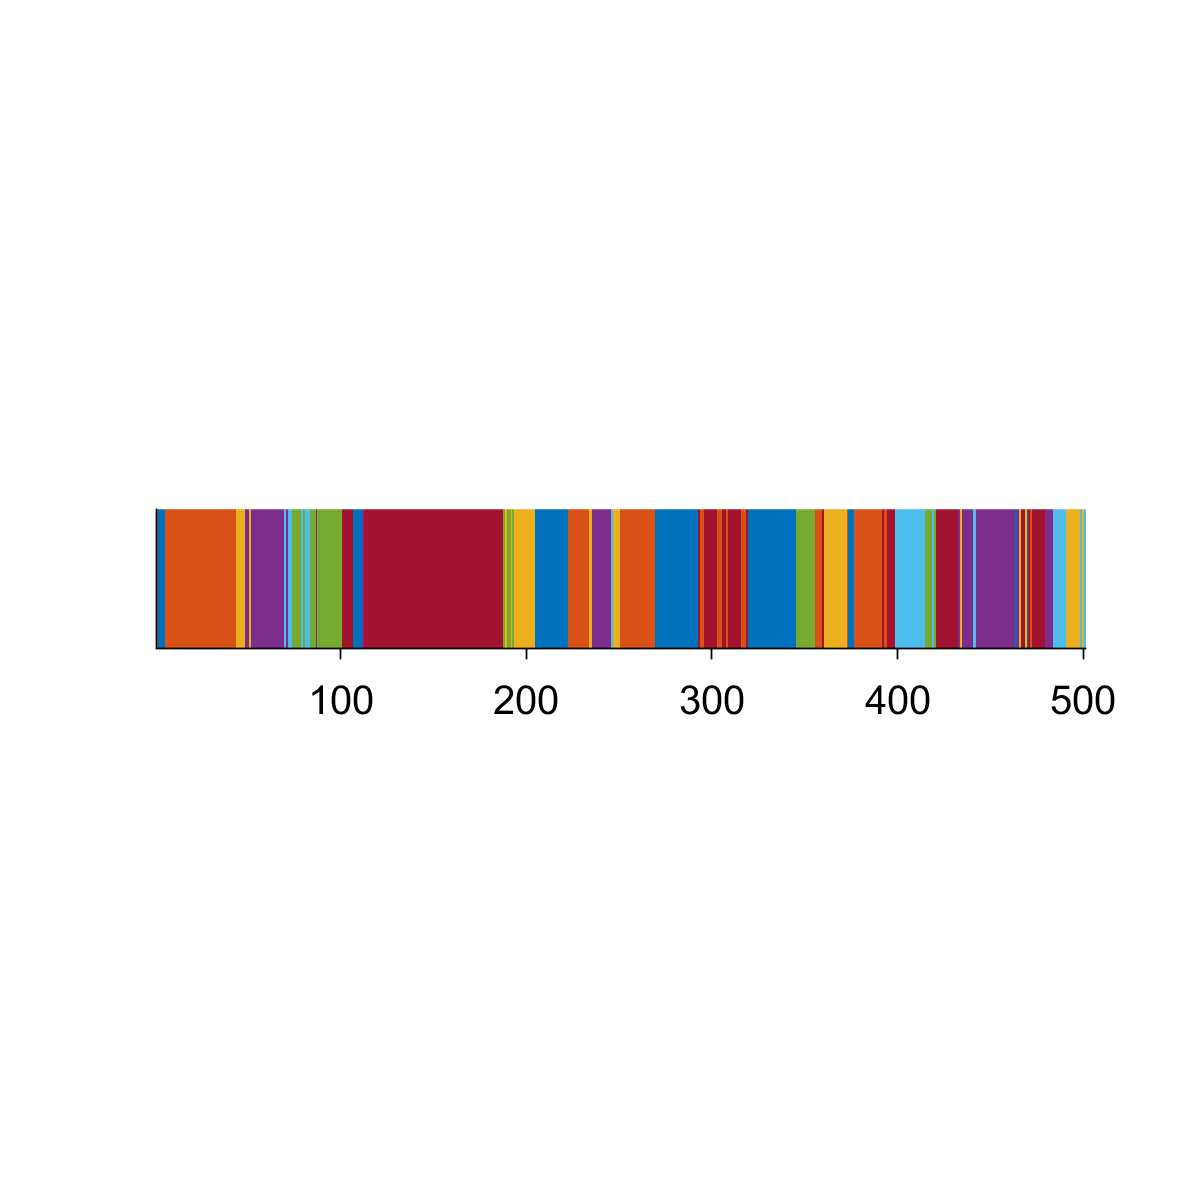

imagesc(cGuesses(idxs(4500:5000),1)')
prepfig;
set(gca,'PlotBoxAspectRatio',[1 0.15 1])
colormap lines
yticks([])